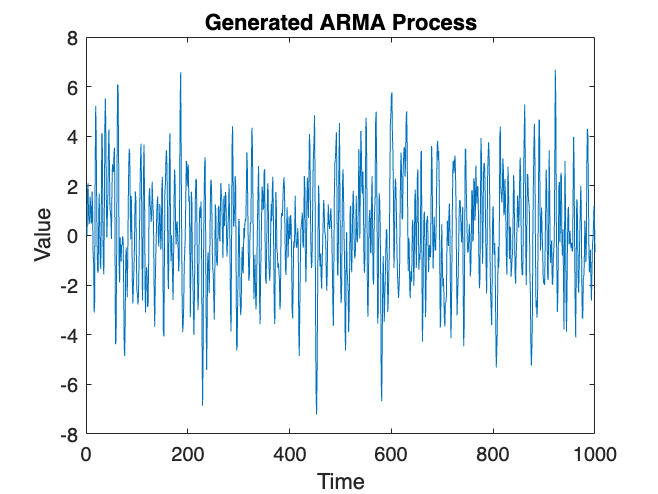

% Example script to generate ARMA process and call the function

% Main code
T = 1000;                   % Number of observations
noise_var = 1;              % Variance of white noise
AR_coeffs = [1, -0.5];    % AR coefficients for AR(2)
MA_coeffs = [0.6];          % MA coefficients for MA(1)

% Call the function with the defined parameters
[arma_process, white_noise] = generate_ARMA(T, noise_var, AR_coeffs, MA_coeffs);

% You can add additional code to plot or analyze the results if needed
figure;
plot(arma_process);
title('Generated ARMA Process');
xlabel('Time');
ylabel('Value');


%==================================================================
% Function definition below
%==================================================================

function [arma_process, white_noise] = generate_ARMA(T, noise_var, AR_coeffs, MA_coeffs)
    % Inputs:
    % T          - number of observations
    % noise_var  - variance of the white noise
    % AR_coeffs  - coefficients of the AR polynomial
    % MA_coeffs  - coefficients of the MA polynomial
    
    % Number of AR and MA terms
    p = length(AR_coeffs);
    q = length(MA_coeffs);
    
    % Preallocate arrays for the ARMA process and white noise
    arma_process = zeros(T, 1);
    white_noise = sqrt(noise_var) * randn(T, 1);  % Generate white noise with specified variance
    
    % Loop to generate ARMA process using the given coefficients
    for t = max(p, q) + 1:T
        % AR part: Sum the past AR terms
        ar_part = 0;
        for i = 1:p
            ar_part = ar_part + AR_coeffs(i) * arma_process(t - i);
        end
        
        % MA part: Sum the past white noise terms
        ma_part = 0;
        for j = 1:q
            ma_part = ma_part + MA_coeffs(j) * white_noise(t - j);
        end
        
        % ARMA process: combine the AR and MA parts plus the current white noise
        arma_process(t) = ar_part + ma_part + white_noise(t);
    end
end